**Instructions on what to turn in: **

Download the folder lab3files to your machine. Inside you will find the following files: 

- lab3_lastname.mlx (rename this file to include your last name)

- newton.m (you will need this code to work on Problem 1) 

What you will need to turn in on Canvas. Upload the following 2 files:

- lab3_lastname.pdf  (instructions on how to generate this below)

- lab3_lastname.zip (a zip folder containing newton.m, secant.m, lab3_lastname.mlx)

How to generate lab3_lastname.pdf. 

Once you have completed all the parts of the assignment and are satisfied with your work, go to View in the top bar and click Output Inline - this makes it so that the grader can easily follow your work. Run lab3_lastname.mlx one more time then go to Live Editor and click Export then choose PDF. A pdf file with the same name as the Live script will be generated with answers to all the parts. 

**Specific instructions for the assignment:**

To make your work easy to grade, please suppress all outputs except for the parts that explictly say not to suppress output. This is most important for any functions you develop. Please make sure everything runs.  

**Problem 1**

**a)** Consider the function $f(x) = e^{\sin^3x} + x^6 - 2x^4 - x^3 - 1$ on the interval $[-2,2]$. Define an anonymous function for $f(x)$ that can take vector input 

e = exp(1);
g = @(x) (sin(x)).^3;
f = @(x) e.^(g(x)) + x.^6 - (2*(x.^4)) - x.^3 - 1;

**b)** Plot this function on the interval $[-2,2]$ using 100 evenly spaced points and identify how many roots are present. 

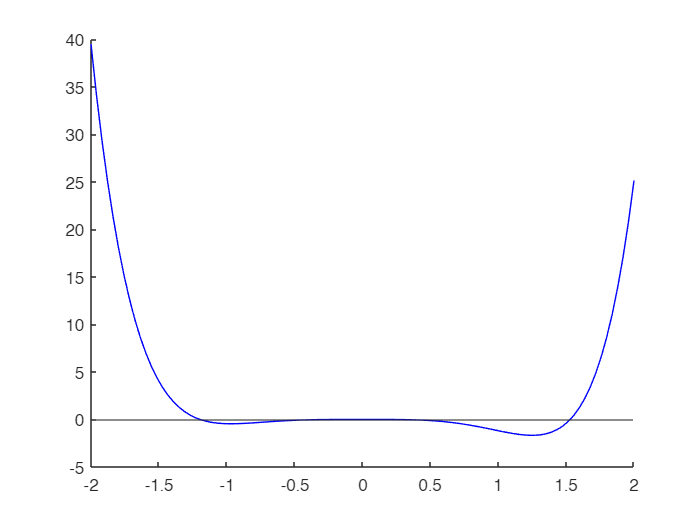

yline(0) %make it easy to see x-axis
hold on;
% Start your code below 
x_axis = linspace(-2, 2, 100);
plot(x_axis, f(x_axis), 'b');

**c)** Define an anonymous function for $f'(x)$. You can find the derivative analytically and then define the function.

dsin3 = @(x) 3.*(sin(x).^2).*(cos(x)); 
de_sin3 = @(x) dsin3(x) .* e.^(g(x)); %chain rule
df = @(x) de_sin3(x) + (6*(x.^5)) - (8*(x.^3)) - (3*(x.^2));
% plot(x_axis, df(x_axis)); % debug haha

**d) **Find all the roots of $f(x)$ to within $10^{-8}$ using Newton's method. Use $\texttt{newton.m}$ provided. Choose an arbitrary number of maximum iterates that you think will be sufficient. Pick a good starting guess that's not the root itself. Recall from class what a good guess for Newton's Method is. You might have to experiment with different initial guess to make sure you get all the roots. *(Do not suppress output of your function call)*

% newton(f,df,p0,Nmax,tol) -> [p,i]
Nmax = 100;
tol = 10.^(-8);

guess_0 = .1;
guess_1 = 1.45;
guess_2 = -1.05;

disp("For the root near x=0")

For the root near x=0


[p_0, i_0] = newton(f, df, guess_0, Nmax, tol);

i =    0, p = 1.0000000000e-01
i =    1, p = 7.506086712725352e-02
i =    2, p = 5.634304805514433e-02
i =    3, p = 4.228959893601501e-02
i =    4, p = 3.173779785120891e-02
i =    5, p = 2.381597098304099e-02
i =    6, p = 1.786952022597292e-02
i =    7, p = 1.340657052674503e-02
i =    8, p = 1.005749981818176e-02
i =    9, p = 7.544605423073798e-03
i =   10, p = 5.659301245963553e-03
i =   11, p = 4.244958606803283e-03
i =   12, p = 3.183993040541914e-03
i =   13, p = 2.388150231772250e-03
i =   14, p = 1.791199561775047e-03
i =   15, p = 1.343449913688581e-03
i =   16, p = 1.007619600836784e-03
i =   17, p = 7.557361531421788e-04
i =   18, p = 5.668547680195397e-04
i =   19, p = 4.252403563142030e-04
i =   20, p = 3.189547394919043e-04
i =   21, p = 2.398392433827315e-04
i =   22, p = 1.804949453332569e-04
i =   23, p = 1.309362430958645e-04
i =   24, p = 1.000266805641073e-04
i =   25, p = 7.229417569131376e-05
i =   26, p = 7.229417569131376e-05


disp("For the root near x=1.53");

For the root near x=1.53


[p_1, i_1] = newton(f, df, guess_1, Nmax, tol);

i =    0, p = 1.4500000000e+00
i =    1, p = 1.557422400398220e+00
i =    2, p = 1.532197228835869e+00
i =    3, p = 1.530146360845113e+00
i =    4, p = 1.530133508668763e+00
i =    5, p = 1.530133508166616e+00



disp("For the root near x=-1.2");

For the root near x=-1.2


[p_2, i_2] = newton(f, df, guess_2, Nmax, tol);

i =    0, p = -1.0500000000e+00
i =    1, p = -1.418618807666219e+00
i =    2, p = -1.287992983022552e+00
i =    3, p = -1.218868035287765e+00
i =    4, p = -1.199119781255269e+00
i =    5, p = -1.197631773122912e+00
i =    6, p = -1.197623722368234e+00
i =    7, p = -1.197623722133570e+00


**e)** From your results above, does it look like Newton's method converges linearly or quadratically to each of the roots? Remember quadratic convergence is faster than linear convergence.

**Your answer as text below: **

It is not excatly clear but the roots near $x=-1\ldotp 2,x=1\ldotp 53$ display quadratic convergence. When we look at the number of stable digits increase at more than a linear rate. This is especially true for $x\approx 1\ldotp 53$. For example at $i=4$the approxmation is accurate to 2 digits. Then it progresses to 5, then, 10. This is evidently not linear. $x\approx -1\ldotp 2$ exhibits similar behavior.

Near $x=0$, we know the root is nearly zero. We can note by the power of 10 that the approxmation is linear. It takes a certain amount of steps for the approxmation to get closer to the real root by a power of 10. This displays linear behavior. 

Lets look at the derivative at these points. 

df(0)

ans = 0

df(1.53)

ans = 14.9606

df(1.1976)

ans = -1.1364

We notice that the roots near 1.2 and 1.53 are **simple zeros **since $f^{\prime } \left(p\right)\not= 0$. This means for an interval around these points, Newton's method will converage **quadratically**. Since the $f^{\prime } \left(0\right)=0$, it implies **it is not **a simple zero. Thus it is will not be approxmiated quadratically in the current function definition\*.

* - I mean here is that there is likely a way to approximate this root quadratically or faster, but we need to make some changes to the function or method.

**Problem 2**

In a separate file, create a function that implements the Secant Method. Then solve $e^x + x = 7$ to within $10^{-6}$ using the Secant Method. Your must print out the approximations at each step like the provided Newton's Method code. Here is the first line of your function:

The outputs are: $p$ the solution and $i$ the number of steps it takes to get a solution. The inputs are: $p0 = 1$ and $p1 = 2$ the two initial guesses, $Nmax$ the maximum number of iterations allowed, $tol$ the accuracy tolerance.

f = @(x) (exp(1).^x) + x - 7;
p0 = 1;
p1 = 2;
Nmax = 200;
tol = 10.^(-6);

[p, i] = secant(f, p0, p1, Nmax, tol);

i =    0, p = 1.0000000000e+00
i =    1, p = 2.0000000000e+00
i =    2, p = 1.5787072479e+00
i =    3, p = 1.6601600999e+00
i =    4, p = 1.6733279622e+00
i =    5, p = 1.6728189973e+00
i =    6, p = 1.6728216981e+00
i =    7, p = 1.6728216986e+00
i =    8, p = 1.6728216986e+00
